DIPUM 3rd edition | Project 1 - Chapter 6 on Transformations Sierpinski triangle Author: Ernesto Colon Date: 2.20.21 ECE419 - Digital Image Processing @ The Cooper Union

clc; clear all; close all

part b - make three affine2d objects, A1, A2, A3 using [b1 b2] = [0 0] [b1 b2] = [0 0.5] and [b1 b2] = [1/4 sqrt(3)/4]

% creating affined2d objects
% first, get the affine matrix form right
A = [0.5 0 0; 0 0.5 0; 0 0 1];

A1 = affine2d([0.5 0 0; 0 0.5 0; 0 0 1]);

% textbook has a mistake in specifying the b1 b2 offsets
A2 = affine2d([0.5 0 0; 0 0.5 0; 0.5 0 1]); 

A3 = affine2d([0.5 0 0; 0 0.5 0; 1/4 sqrt(3)/4 1]);

part c - generate 100,000 points of the Sierpinski triangle using this iterative procedure

% 1. Initialize xy to [0 0]
% 2. Repeatedly generate the next point using the code 
% xy(end+1,:) = transformPointsForward(A,xy(end,:)), where A is random is 
% randomly selected from the three affine2d objects constructed in part (b)

% initialize xy
xy = [0 0];

% iterate 
for iter = 1: 100000
    % select affine2d object at random
    rand_int = randi([1 3], 1 ,1);
    
    switch rand_int
        case 1
            A = A1;
        case 2
            A = A2;
        case 3
            A = A3;
        otherwise
            error('Not a valid affine2d object')
    end
    
    xy(end+1,:) = transformPointsForward(A,xy(end,:));
end

PLot the points using scatter and dot markers. 

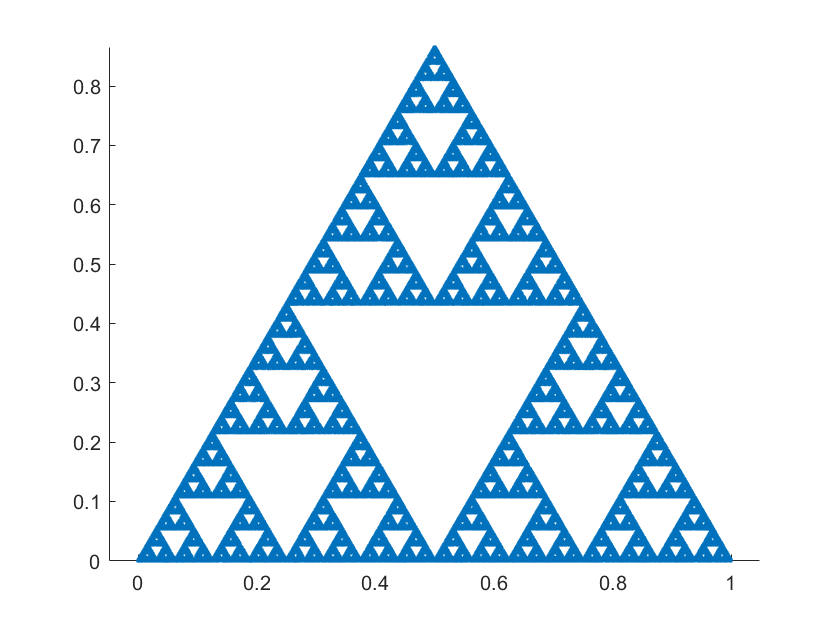

figure
scatter(xy(:,1), xy(:,2), '.')
axis('equal')